% Sample code to generate plot from data aquired from calibrated pendulum
% Use this code to plot the oscillating pendulum data
% Time period and frequency should be calulated separately.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Date: August 5th, 2020
% Dr. Vibhav Durgesh
% Rev 0.0
% Rev 1.0 Removed redundant part in the code
% User has to provide appropriate information - see beginning of code
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all
close all
clc

## Start user required information

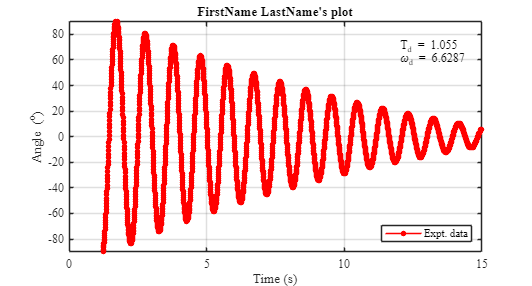

fid = fopen('../Data/Student_Name_AngVsTime.dat');
tline = fgetl(fid);
data = fscanf(fid, '%f \n', [2 inf]);
x = data(1,:);
y = data(2,:);
fclose(fid);

% Generating figure with specific size
figure (1)
set(gcf,'unit','inches','position',[0.50 0.50, 6.50 3.50],...
    'defaultaxesfontsize',10,'defaultaxesfontname','times');
% Plotting data
plot(x,y,'-ro','markersize',4,'markerfacecolor','r');
xlabel('Time (s)')
ylabel('Angle (^{o})')
grid on

ylim([-90 90])
xlim([0 15])

legend('Expt. data','location','Southeast')
title('FirstName LastName''s plot')

text(12,70,'T_d = 1.055','Fontname','times')
text(12,60,'\omega_d = 6.6287','Fontname','times')

## Saving the files in png and pdf format

figName = ('../Figures/Student_Name_Expt02_Postprocess');
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf, 'Position');
set(gcf, 'PaperSize', figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')